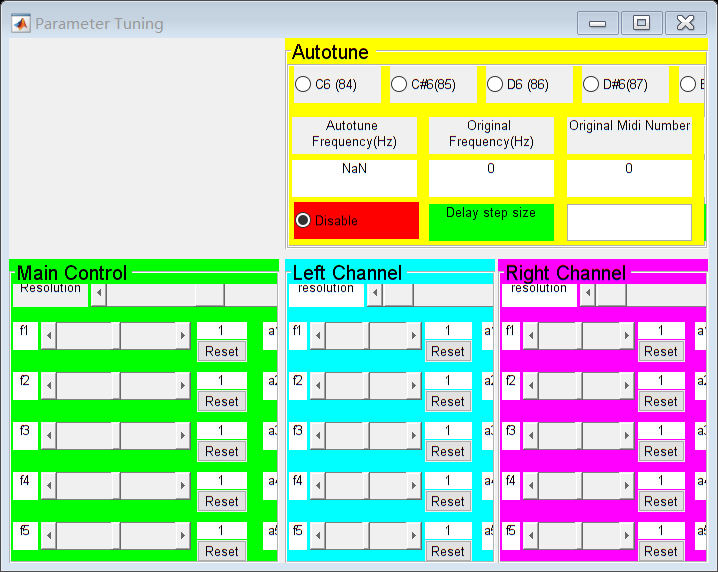

% Main figure
hMainFigure = figure( ...
    'Name','Parameter Tuning', ...
    'MenuBar','none', ...
    'Toolbar','none', ...
    'HandleVisibility','callback', ...
    'NumberTitle','off', ...
    'IntegerHandle','off');

A = imread("spectral1.png");
I =imresize(A, 0.5);
hButton = uicontrol('Parent',hMainFigure,...
                    'CData',I,'Position',[3,480,1600/2.72,900/2.72]);

p1 = uipanel('Parent',hMainFigure,'Position',[0 0 0.386 0.58],'BackgroundColor','green','Title','Main Control','FontSize',12);
p2 = uipanel('Parent',hMainFigure,'Position',[0.395 0.598 0.605 0.402],'BackgroundColor','yellow','Title','Autotune','FontSize',12);
p3 = uipanel('Parent',hMainFigure,'Position',[0.395 0 0.3 0.58],'BackgroundColor','cyan','Title','Left Channel','FontSize',12);
p4 = uipanel('Parent',hMainFigure,'Position',[0.7 0 0.3 0.58],'BackgroundColor','magenta','Title','Right Channel','FontSize',12);

autotune = parameterRef;
autotune.name = "autotune";
autotune.value = NaN;
autotune.step = 1; %flag
midi(p2,autotune);

freq_org = 0;
freqValueDisplay = uicontrol('Parent',p2, ...
        'Style','text', ...
        'Position', [115 40 100 30], ...
        'BackgroundColor','white', ...
        'String',freq_org);

midi_org = 0;
midiValueDisplay = uicontrol('Parent',p2, ...
        'Style','text', ...
        'Position', [225 40 100 30], ...
        'BackgroundColor','white', ...
        'String',freq_org);

deviation = parameterRef;
deviation.value = 2000;
deviation.step = 100;
parameterTuning_linear_nolabel(p2,deviation,0,2001,[440,75,270,26],[713,75,40,26],[756,75,50,26],[815,75,60,26],[876,75,48,26]);

set_freq = parameterRef;
set_freq.value = 300;
set_freq.step = 1;
parameterTuning_linear_nolabel(p2,set_freq,20,2000,[440,40,270,26],[713,40,40,26],[756,40,50,26],[815,40,60,26],[876,40,48,26]);

set_speed_ratio = parameterRef;
set_speed_ratio.value = 1;
set_speed_ratio.step = 0.01;
parameterTuning_nolabel(p2,set_speed_ratio,0.5,2,[440,5,270,26],[713,5,40,26],[756,5,50,26],[815,5,60,26],[876,5,48,26]);

[pitch_ratio,amplitude_ratio,beat_ratio,vibrato_width,vibrato_rate,freq_lowEnd,...
    freq_highEnd,resolution,f1,f2,f3,f4,f5,a1,a2,a3,a4,a5,t1,t2,t3,t4,t5] = main_panel(p1);

% [pitch_ratio_l,amplitude_ratio_l,time_delay_l,vibrato_width_l,vibrato_rate_l,freq_lowEnd_l,...
%     freq_highEnd_l,resolution_l,f1_l,f2_l,f3_l,f4_l,f5_l,a1_l,a2_l,a3_l,a4_l,a5_l,...
%     t1_l,t2_l,t3_l,t4_l,t5_l] = left_panel(p3);
% 
% [pitch_ratio_r,amplitude_ratio_r,time_delay_r,vibrato_width_r,vibrato_rate_r,freq_lowEnd_r,...
%     freq_highEnd_r,resolution_r,f1_r,f2_r,f3_r,f4_r,f5_r,a1_r,a2_r,a3_r,a4_r,a5_r,...
%     t1_r,t2_r,t3_r,t4_r,t5_r] = left_panel(p4);

delay_stepsize = parameterRef;
delay_stepsize.value = 0.001;
Edit(p2,delay_stepsize,[225 5 100 30]);

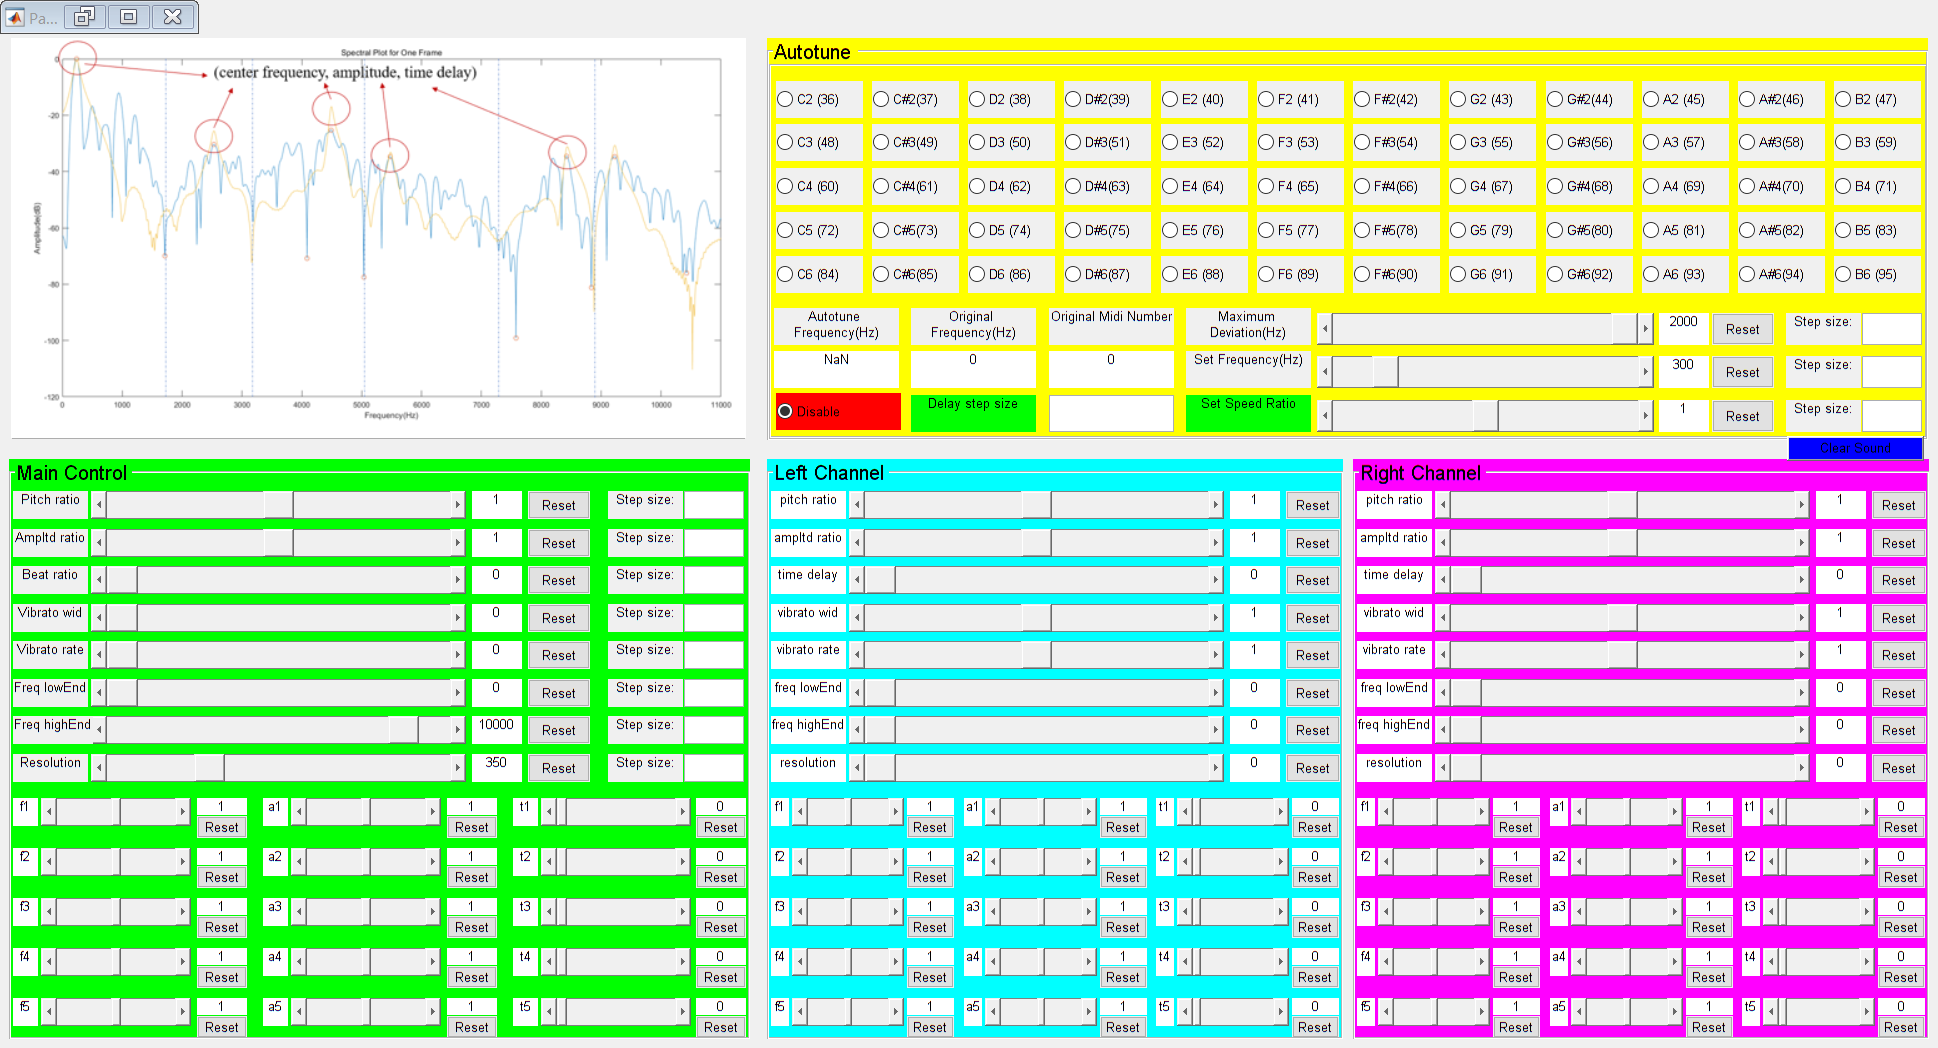

fs = 44100;
frame = 128;
buffer_size = 8;
% frame = 256;
% buffer_size = 4;

% afr = dsp.AudioFileReader('didadi_vocal.wav','ReadRange',[156.5*fs 222*fs],'SamplesPerFrame',frame);
% afr = dsp.AudioFileReader('speech.wav','ReadRange',[1 278*fs],'SamplesPerFrame',frame);
% afr = dsp.AudioFileReader('verse1_vocal.wav','SamplesPerFrame',frame);
afr = dsp.AudioFileReader('Papillon_vocal.wav','SamplesPerFrame',frame); % ,'ReadRange',[10*fs 170*fs]

% acc = audioread('verse1_accompaniment.wav');
acc = audioread('Papillon_accompaniment.wav');


acc = (acc(:,1)+acc(:,2))/2;
acc = acc';

adw = audioDeviceWriter('SampleRate', afr.SampleRate);

c1 = 80; %80
c2 = 350; %300
c3 = 1000;
Phi = 0;

buffer = zeros(1,5*fs);
sst = 1;

sample_buffer = zeros(1,buffer_size*frame);
for i = 1:buffer_size
    audio = afr();
    audio = (audio(:,1)+audio(:,2))/2;
    sample_buffer(1+(i-1)*frame:i*frame) = audio';
end

clear_it(hMainFigure,afr,[1424 463 110 20]);

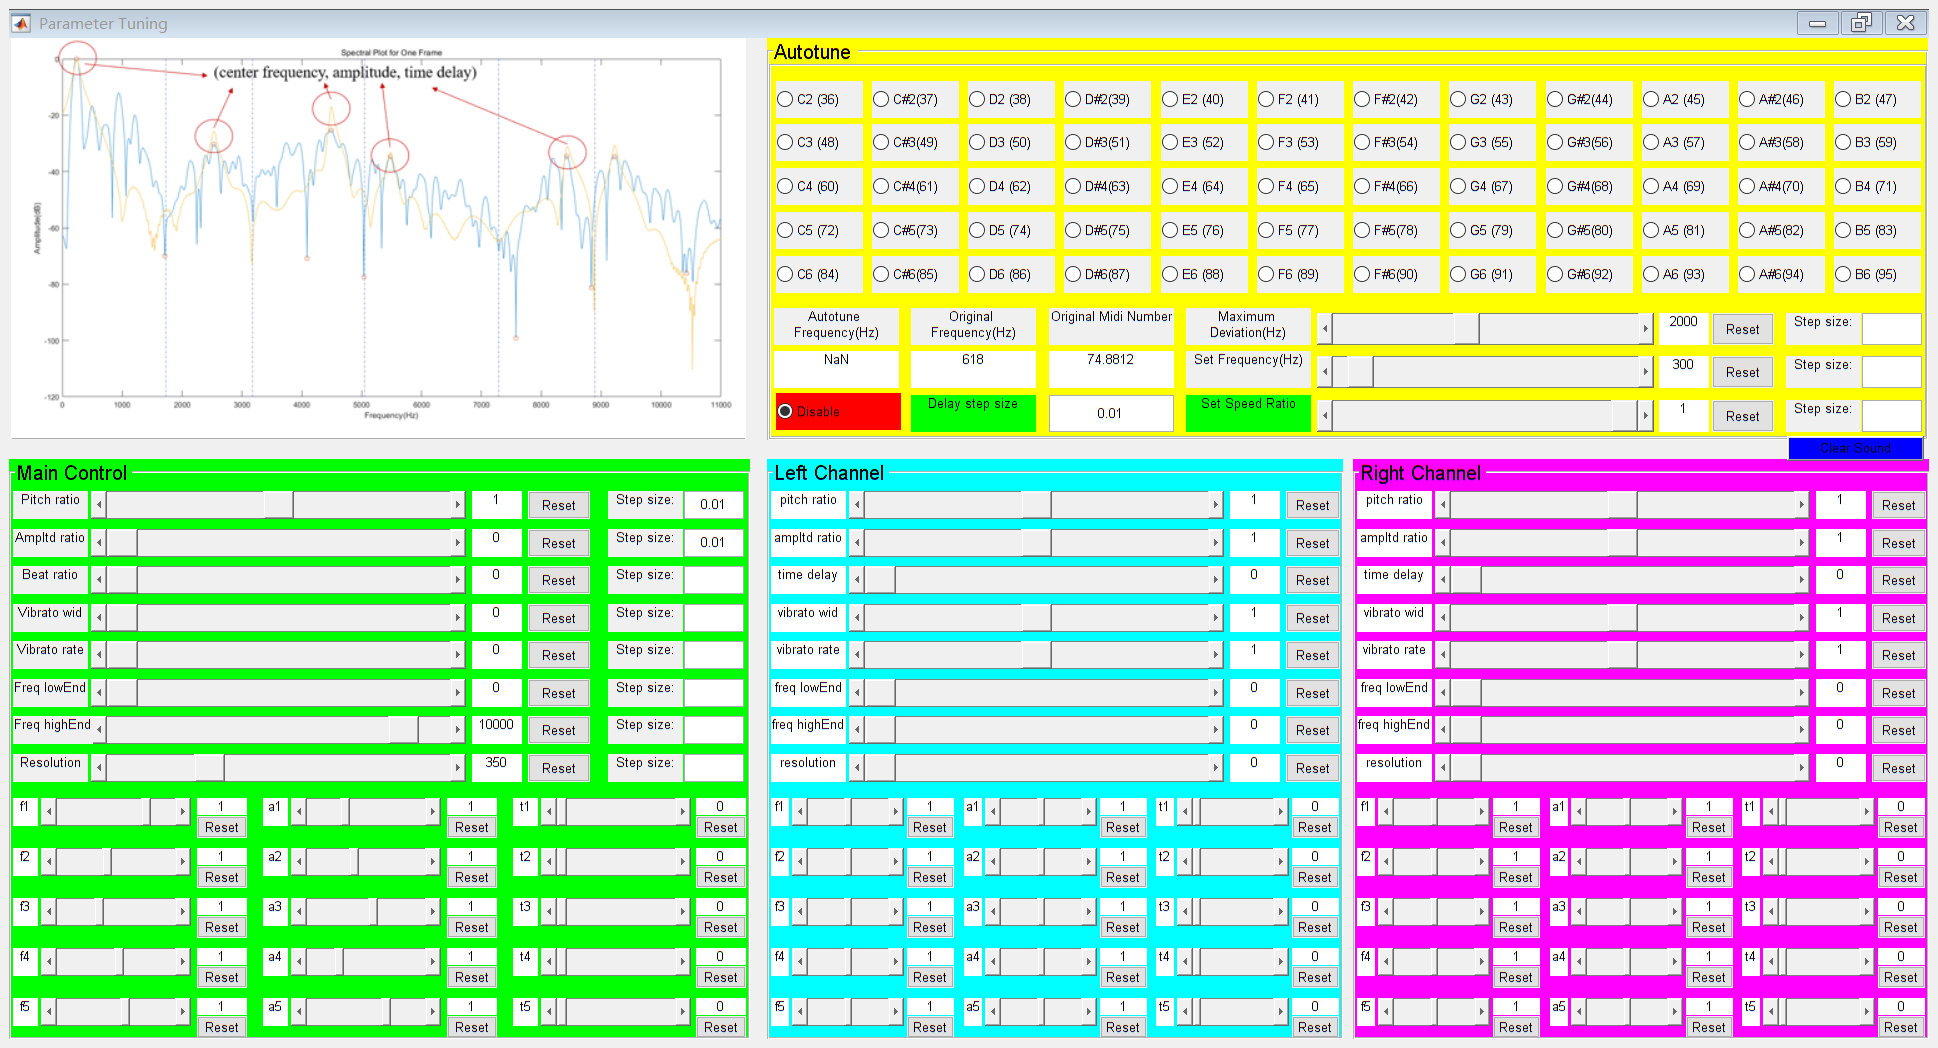

x = 1; % frequency
f_speed_ratio = 1;
ct = 0;
x_array = [1 1 1 1 1];

x2 = 1; % amplitude
x2_array = [1 1 1 1 1];

x3_array = [0 0 0 0 0]; % time delay

x_auto = 300; % autotune frequency
store_auto = 300;

x_dev = 2000;
x_beat = 0;
x_vwidth = 0;
x_vrate = 0;
x_flow = 0;
x_fhigh = 10000;
x_resolution = 350;


acc_count = 0;
while ~isDone(afr)
    
     audio = afr(); %[1024,2]
    audio = (audio(:,1)+audio(:,2))/2;
%     audio = audio(:,1);

    sample_buffer(1:(buffer_size-1)*frame) = sample_buffer(1+frame:end);
    sample_buffer((buffer_size-1)*frame+1:end) = audio';
    sample = sample_buffer;
    
    if x_flow < freq_lowEnd.value
        x_flow = x_flow + freq_lowEnd.step;
    elseif x_flow > freq_lowEnd.value
        x_flow = x_flow - freq_lowEnd.step;
    end
    f_low = round(x_flow);
    
    if x_fhigh < freq_highEnd.value
        x_fhigh = x_fhigh + freq_highEnd.step;
    elseif x_fhigh > freq_highEnd.value
        x_fhigh = x_fhigh - freq_highEnd.step;
    end
    f_high = round(x_fhigh);
    
    if x_resolution < resolution.value
        x_resolution = x_resolution + resolution.step;
    elseif x_resolution > resolution.value
        x_resolution = x_resolution - resolution.step;
    end
    resolt = round(x_resolution);
    
    Parameter = FOF_process(sample,fs,f_low,f_high,resolt);
    [~,col] = size(Parameter);

    if col > 0
        
        f0 = Parameter(1,1);
        
        if f_speed_ratio < set_speed_ratio.value
            f_speed_ratio = f_speed_ratio + set_speed_ratio.step;
        elseif f_speed_ratio > set_speed_ratio.value
            f_speed_ratio = f_speed_ratio - set_speed_ratio.step;
        end
        step = round(fs/(f0*f_speed_ratio));
        
        freq_ratio_array = [f1.value,f2.value,f3.value,f4.value,f5.value];
        amp_ratio_array = [a1.value,a2.value,a3.value,a4.value,a5.value];
        time_delay_array = [t1.value,t2.value,t3.value,t4.value,t5.value];
        
        
        if ~isnan(autotune.value)
            if store_auto ~= set_freq.value
                autotune.step = 0;
            end
            
            if autotune.step == 0 % set frequency
                
                if x_auto < set_freq.value
                    x_auto = x_auto + set_freq.step;
                elseif x_auto > set_freq.value
                    x_auto = x_auto - set_freq.step;
                end
                store_auto = set_freq.value;
                freqq = x_auto;
            elseif autotune.step == 1 % midi
                freqq = autotune.value;
                x_auto = autotune.value;
                store_auto = set_freq.value;
            end
                
            if f0 > 800
                r = 1;
            else
                
                if x_dev < deviation.value
                    x_dev = x_dev + deviation.step;
                elseif x_dev > deviation.value
                    x_dev = x_dev - deviation.step;
                end
                dev = x_dev;
                if freqq > f0
                    r = min(freqq,f0 + dev)/f0;
                else
                    r = max(freqq,f0 - dev)/f0;
                end
            end  
            
        else
            r = 1;
                
        end
        
        
        ct = ct + 1;
        if mod(ct,50) == 0 && f0 < 800
            freq_org = f0;
            midi_org = log2(freq_org/440)*12+69;
            set(freqValueDisplay,'String',num2str(freq_org));
            set(midiValueDisplay,'String',num2str(midi_org));
        end
   
        if x < pitch_ratio.value
            x = x + pitch_ratio.step;
        elseif x > pitch_ratio.value
            x = x - pitch_ratio.step;
        end
        
        if x2 < amplitude_ratio.value
            x2 = x2 + amplitude_ratio.step;
        elseif x2 > amplitude_ratio.value
            x2 = x2 - amplitude_ratio.step;
        end
    
        for i = 1:col
            
            beta = Parameter(4,i);
            t = pi/beta;
            alpha = min(Parameter(3,i),c1)*pi;
            
            f = Parameter(1,i)*r*x;
            if i <= 5
                if x_array(i) < freq_ratio_array(i)
                    x_array(i) = x_array(i) + pitch_ratio.step;
                elseif x_array(i) > freq_ratio_array(i)
                    x_array(i) = x_array(i) - pitch_ratio.step;
                end
                f = f*x_array(i); % *ratio(i);
            end
            
            omega = 2*pi*f;
            kn1 = [0:fs*t-1]/fs;
%                 vibrato_width = 0.01*f;
%                 vibrato_rate = randi(10);
            
            if x_vwidth < vibrato_width.value
                x_vwidth = x_vwidth + vibrato_width.step;
            elseif x_vwidth > vibrato_width.value
                x_vwidth = x_vwidth - vibrato_width.step;
            end
            
            if x_vrate < vibrato_rate.value
                x_vrate = x_vrate + vibrato_rate.step;
            elseif x_vrate > vibrato_rate.value
                x_vrate = x_vrate - vibrato_rate.step;
            end
            
            s1 = (1 - cos(beta*kn1))/2.*exp(-alpha*kn1).*sin(omega*kn1+x_vwidth*f0*cos(2*pi*x_vrate*kn1)+Phi);
            ts = ceil(-log(0.003)/(alpha*t));
            kn2 = [t*fs:t*fs*ts]/fs;
            s2 = exp(-alpha*kn2).*sin(omega*kn2 + x_vwidth*f0*cos(2*pi*x_vrate*kn2)+Phi);
            s = [s1 s2];

            if Parameter(3,i) > c2 && Parameter(3,i) <= c3
                s = conv(s,rand(1,length(s)+1)*2-1);
            elseif Parameter(3,i) > c3
                s = conv(s,rand(1,length(s)+1)*2-1);
                s = conv(s,rand(1,length(s)+1)*2-1);
            end

            amp = Parameter(2,i)*x2;
            if i <= 5
                if x2_array(i) < amp_ratio_array(i)
                    x2_array(i) = x2_array(i) + amplitude_ratio.step;
                elseif x2_array(i) > amp_ratio_array(i)
                    x2_array(i) = x2_array(i) - amplitude_ratio.step;
                end
                amp = amp*x2_array(i);
            end
            
            s = s/max(abs(s))*amp;
            
            % add dispersion
            dl = 0;
            if i <= 5
                if x3_array(i) < time_delay_array(i)
                    x3_array(i) = x3_array(i) + delay_stepsize.value;
                elseif x3_array(i) > time_delay_array(i)
                    x3_array(i) = x3_array(i) - delay_stepsize.value;
                end
                dl = round(fs*x3_array(i));
            end
            
            start = sst + dl;
            buffer(start:start+length(s)-1) = buffer(start:start+length(s)-1)+s;
            
            
%             while step < frame/2
%                 step = 2*step;
%             end
%             sstt = sst + step;
%             while sstt < frame
%                 buffer(sstt+ dl:sstt+ dl+length(s)-1) = buffer(sstt+ dl:sstt+ dl+length(s)-1)+s;
%                 sstt = sstt + step;
%             end
            
        end
        
        sst = sst + step;
        while sst < frame
            sst = sst + step;
        end
    else
        sst = sst + frame;
    end
    
    sst = sst - frame;
    
    if x_beat < beat_ratio.value
        x_beat = x_beat + beat_ratio.step;
    elseif x_beat > beat_ratio.value
        x_beat = x_beat - beat_ratio.step;
    end
    
    while sst >= frame
        audio = afr();
        sst = sst - frame;
        
        output = buffer(1:frame);
        output = output/120;
        
        output =  output + acc(1 + acc_count*frame:frame + acc_count*frame)/2*x_beat;
        acc_count = acc_count + 1;

        adw(output');

        buffer(1:end-frame) = buffer(frame+1:end);
        buffer(end-frame+1:end) = zeros(1,frame);
    end
    if sst == 0
        sst = 1;
    end
    
    drawnow limitrate
    
    output = buffer(1:frame);
    output = output/120;
    
    output =  output + acc(1 + acc_count*frame:frame + acc_count*frame)/2*x_beat;
    acc_count = acc_count + 1;

    adw(output');

    buffer(1:end-frame) = buffer(frame+1:end);
    buffer(end-frame+1:end) = zeros(1,frame);
    
end


for i = 1:round(3*fs/frame)
    output = buffer(1:frame);
    output = output/120;

    adw(output');

    buffer(1:end-frame) = buffer(frame+1:end);
    buffer(end-frame+1:end) = zeros(1,frame);
end

release(afr); 
release(adw);